clc
clear
close all

## ** Load Data


% fileB = '1st_Trial_0.2Hz.txt';
% fileB = '2nd_Trial_0.2Hz.txt';

% fileB = '1st_Trial_0.25Hz.txt';
% fileB = '2nd_Trial_0.25Hz.txt';

% fileB = '1st_Trial_0.30Hz.txt';
% fileB = '2nd_Trial_0.30Hz.txt';

% fileB = '1st_Trial_0.35Hz.txt';
% fileB = '2nd_Trial_0.35Hz.txt';

% fileB = '1st_Trial_0.3167Hz.txt';
% fileB = '2nd_Trial_0.3167Hz.txt';

% fileB = '1st_Trial_0.3333Hz.txt';
fileB = '2nd_Trial_0.3333Hz.txt';

% fileB = '1st_Trial_0.3667Hz.txt';
% fileB = '2nd_Trial_0.3667Hz.txt';

% fileB = '1st_Trial_0.4000Hz.txt';
% fileB = '2nd_Trial_0.4000Hz.txt';

% fileB = '1st_Trial_0.4500Hz.txt';
% fileB = '2nd_Trial_0.4500Hz.txt';

% fileB = '1st_Trial_0.5000Hz.txt';
% fileB = '2nd_Trial_0.5000Hz.txt';

% lb3 = load('lb3.mat'); %bandpass filter
lb3CB = load('lb3CB.mat');

B = readtable(fileB);

## Get RSS, Time, BER, Magnitude, and Phase Data

Bamp = table2array(B(:,2));
time = length(Bamp);
Bt = 1:time; %Did this because for some reason time was not like 1, 2, 3, 4, and instead was like 1, 2, 2, 3, 4, 4

## Plot Time Domain for Chest Belt

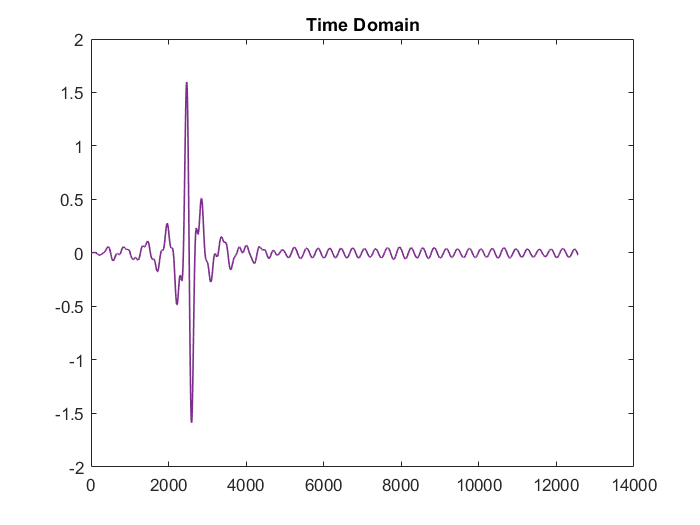

figure
plot(Bt, filter(lb3CB.lb3CB, Bamp),'LineWidth',1, 'Color', '#7E2F8E');
title("Time Domain");

## Plot Frequency Domain for Chest Belt

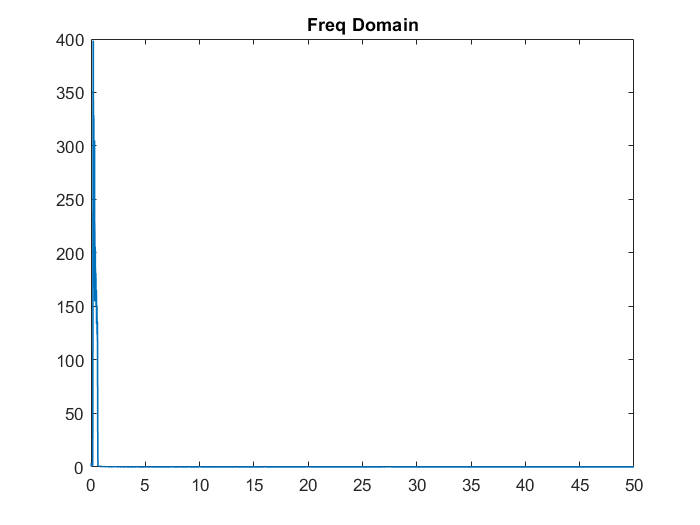

 Nsamps = length(Bamp); 
    Nhalf = Nsamps/2;
    fs = 100;
    f = fs*(0:Nsamps/2-1)/Nsamps;
    
 yfreq = abs(fft(filter(lb3CB.lb3CB,Bamp)));
 figure
 plot(f, yfreq(1:Nsamps/2), 'LineWidth', 1, 'Color', '#0072BD');
 title("Freq Domain");

## Extracting Breathing Frequency

[pks, loc] = findpeaks(yfreq(1:Nsamps/2), f,"MinPeakProminence", 0.05 ); % finds peaks in frequency
[M1, I1] = max(pks);
finalFreq = loc(I1);

%this does not work for a couple of the frequencies so I had to manually
%look at the frequency domain plot.